# **drawCatenary**

Draw 2-D catenary 

## Description

The catenary is the curve that an idealized hanging homogeneous  chain or cable assumes under its own weight when supported only at its ends [1]. The coordinates of the curve points are given by [2]

$\begin{array}{l}
x\left(s\right)=x_1 +\lambda \left\lbrack {\mathrm{sinh}}^{-1} \left(\frac{s}{\lambda }\right)-{\mathrm{sinh}}^{-1} \left(\frac{s_1 }{\lambda }\right)\right\rbrack \\
y\left(s\right)=y_1 +\lambda \left\lbrack \sqrt{1+{\left(\frac{s}{\lambda }\right)}^2 }-\sqrt{1+{\left(\frac{s_1 }{\lambda }\right)}^2 }\right\rbrack 
\end{array}$,   $s_1 \le s\le s_2$

where *s is arc-length parameter, *$\left(x_1 ,y_1 \right)$ are the coordinates of the catenary starting point, *and *$\lambda \;$is characteristic length. The length of catenary $L\;$, the horizontal distance (span) $\Delta x>0$ and vertical distance $\Delta y$ between the two supports* are* given by

$L=s_2 -s_1$,    $\Delta x=x_2 -x_1$,   $\Delta y=y_2 -y_1$.

The catenary appex $\left(x_a ,y_a \right)$ is at $s=0$. The sags  of  of the supports are

$h_1 =y_1 -y_a$,   $h_2 =y_2 -y_a$

## Syntax

drawCatenary(,x1,y1,dx,dy,L)

drawCatenary(,x1,y1,dx,dy,'-L',L)

drawCatenary(,x1,y1,dx,dy,'-h',h1)

drawCatenary(x1,y1,dx,dy,L,LineSpec)

drawCatenary(x1,y1,dx,dy,L,'-np',np)

p = drawCatenary(__)

## Description

drawCatenary(x1,y1,dx,dy,L) draw catenary  with default number of points. 

drawCatenary(x1,y1,dx,dy,L,LineSpec)  sets the line style, marker symbol, and color.

drawCatenary(x1,y1,dx,dy,L,'-np',np) draw catenary with np points.

p = drawCatenary(__) returns structure with fields contain x-value and y-value for the curve.

## Method

For calculation of the coordinates of the curve **drawCatenary **call function **evalCatenary( x1,y1,lambda, s1, s)  **which returns coordinates *x *and *y *of the curve at given values of parameter s. For usage of **evalCatenary **see Example 1.

When span $\Delta x$, verical distance between supports $\Delta y$, and catenary lengt $L$ are given then characteristic length $\lambda$ is obtained by solving the equation


$$2\lambda^2 \mathrm{cosh}\frac{\Delta x}{\lambda }=L^2 -{\Delta y}^2$$


Once  $\lambda$ is known one can calculate parameter value at end points  by 

$s_1 =\frac{1}{2}\left(\sqrt{\frac{L^2 -{\Delta y}^2 +4\lambda^2 }{L^2 -{\Delta y}^2 }}-L\right)$,     $s_2 =L-s_1$.

When span $\Delta x$, verical distance between supports $\Delta y$, and sag $h_1$of start support are given  then characteristic length $\lambda$ is obtained by solving the equation


$$\lambda \left\lbrack {\mathrm{cosh}}^{-1} \left(1+\frac{{\Delta y+h}_1 }{\lambda }\right)+{\mathrm{cosh}}^{-1} \left(1+\frac{h_1 }{\lambda }\right)\right\rbrack =\Delta x$$


Once  $\lambda$ is known one can calculate parameter value at end points  by 

$s_1 =-\sqrt{h_1 \left(h_1 +2\lambda \right)}$,     $s_2 =\sqrt{\left(h_1 +\Delta y\right)\left(h_1 +\Delta y+2\lambda \right)},$

where we assume that the appex is between suports.

The solution of above equations solution is obtained numerically by using MATLAB function [fzero](https://www.mathworks.com/help/matlab/ref/fzero.html)**. **Default initial quess is in both cases is $\lambda =1$.

Catenary is plotted by MATLAB function [plot](https://www.mathworks.com/help/matlab/ref/plot.html).

## Arguments

### Input Arguments

**x1 - **x-coordinate of starting point (real scalar)

**y1 **- y-coordinate of starting point (real scalar)

**dx **- horizontal distance between end points (real scalar, >0)

**dy **- vertical distance between end points (real scalar)

### **Optional arguments**

**L **- catenary length (real scalar ,>0)

### Optional Name-Value Pair Input Arguments

**'-L', L **- catenary length (real scalar >0)

**'-h', h1 **- the vertical  distance from appex to starting point (real scalar)

**'-np',** **np **- number of points along the curve ( scalar integer value, > 1)

**'-guess',z0 **- initial quess for **fzero**, (real scalar, > 0)

***LineSpec*** - specifies line properties, see [Line Properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html).

### Optional Output Arguments

**p **- structure with field.

- p.type - 'Catenary'

- p.x - x-coordinates of the curve (real column vector)

- p.y - y coordinates of the curve (real column vector)

- p.xa - x coordinate of the curve appex

- p.ya - y coordinate of the curve appex

- p.lambda - characteristic length

- p.s1 - parameter starting value (real scalar)

- p.s2 - parameter end value (real scalar)

- p.L - catenary length

- p.dx - horizontal distance between end points

- p.dy - vertical distance between end points

- p.style - line style 

- p.width - line width 

- p.color - line color

## Examples

### Example 1

Example from [2] (pp 132-133).

%Data 
a = 10;
b = 16;
L = 24;
%Values from book
%c  = 2.530;  % characteristic length
%xa = 2.96;  % appex x position
%ya = 4.470;
figure
axis equal
hold on
p=drawCatenary(0,0,a,b,L)

p = struct with fields:
      type: 'Catenary'
         x: [100×1 double]
         y: [100×1 double]
        xa: 2.9622
        ya: -1.9394
    lambda: 2.5323
        s1: -3.6856
        s2: 20.3144
         L: 24
        dx: 10
        dy: 16
        h1: 1.9394
        h2: 17.9394
        d1: -2.9622
        d2: 7.0378
        xk: [0 10 2.9622]
        yk: [0 16 -1.9394]
     color: [0 0.4470 0.7410]


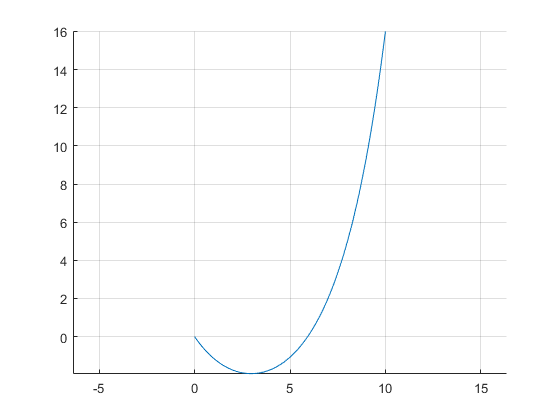

grid on

### Example 2

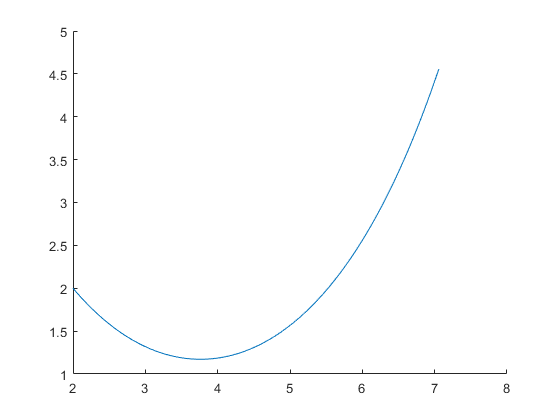

figure
hold on
c = 2; % characteristic length
x1 = 2; y1 = 2; % starting point
L1 = 2; % lengt of left part of catenary 
L2 = 5; % lenfth of right part of catenary
[x,y] = evalCatenary(c,x1,y1,-L1,linspace(-L1,L2));
plot(x,y)

### Example 3

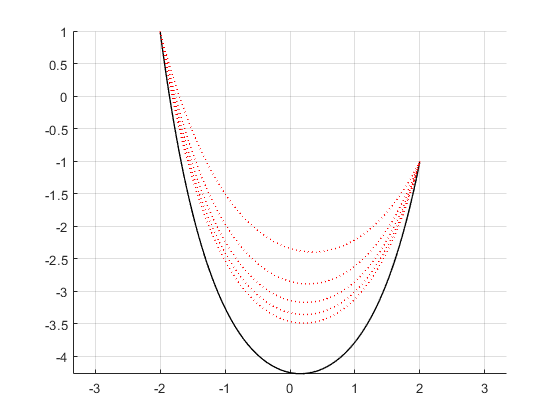

figure
hold on
axis equal       % !!!
L = 10;          % catenaary length
x1 = -2; y1 = 1; % start point
dx = 4; dy = -2; % horizontal and verticale distance between suports
% draw curves
drawCatenary(x1,y1,dx,dy,L,'LineWidth',1,'Color','k');
for k = 2:6
    drawCatenary(x1,y1,dx,dy,L*k/(k+1),'LineWidth',1,'LineStyle',':','Color','r');
end
grid on

### **Example 4**

drawInit
title('Catenary')
col = 0.8*[1 1 1]; % light gray
h1 = 1; % sag of first point
x1 =-2; y1 = 1; % start point location
dx = 2; dy = 1; % horizontal and vertical distance between supports
c = drawCatenary(x1,y1,dx,dy,'-h',h1,'LineWidth',2,'Color','b')

c = struct with fields:
      type: 'Catenary'
         x: [100×1 double]
         y: [100×1 double]
        xa: -1.1301
        ya: -2.2204e-16
    lambda: 0.4892
        s1: -1.4065
        s2: 2.4406
         L: 3.8471
        dx: 2.0000
        dy: 1.0000
        h1: 1.0000
        h2: 2.0000
        d1: -0.8699
        d2: 1.1301
        xk: [-2 -4.4409e-16 -1.1301]
        yk: [1 2.0000 -2.2204e-16]
     color: [0 0 1]


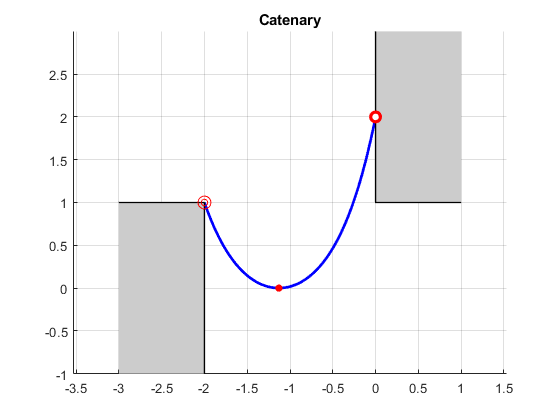

% mark appex
scatter(c.xa,c.ya,30,'r','filled')
% draw wals
b1=fillRect(col,1,2,c.x(end),c.y(end),0,'-pos',4,'EdgeColor','none');
drawRect(1,2,c.x(end),c.y(end),0,'-v',4,2,'-pos',4,'k','LineWidth',1)
b2=fillRect(col,1,2,c.x(1),c.y(1),0,'-pos',9,'EdgeColor','none');        
drawRect(1,2,c.x(1),c.y(1),0,'-v',2,4,'-pos',9,'k','LineWidth',1);
% draw pins
drawDonut(0.15,0.075,c.x(1),c.y(1),'r')
fillDonut('r','w',0.15,0.075,c.x(end),c.y(end))
grid on

## **See Also**

## References

[1]  [WikipediA, Catenary](https://en.wikipedia.org/wiki/Catenary)

[2] [J.Prescott, Mechanics of Particls and Rigid Bodies, Longmans, 1966, Ch 8](https://archive.org/details/MechanicsOfParticlesRigidBodies)